# Compare Airspeed

## **Load WR data**

load('../data/dc_corr')
ii_d = [6 28 8];% deflg, demem, frmtc

## Load Insec/Bird Birdscan

load('BS/Sempach_2018_combined')
BS.air=BS.flight-BS.wind;

add value of BS location.

lat = 47.128054;
lon = 8.192377;
alt = 540;

Add seasonal variables

t=datetime('2018-01-01'):datetime('2019-01-01');
season = datetime([737121 737184 737273 737384 737121+365],'ConvertFrom','datenum');
season_label = {'Spring (02-Mar  - 04-May)','Summer (4-May - 1-Aug)','Autumn (1-Aug - 20-Nov)','Winter (20-Nov - 02-Mar)'};
BS.season = sum(bsxfun(@gt, datenum(BS.time_string), datenum(season)),2);

Add day assocaite

[~,BS.day_id] = ismember(dateshift(BS.time_string,'start','day'),t);

## Speed and Direction

Filter uncertainty

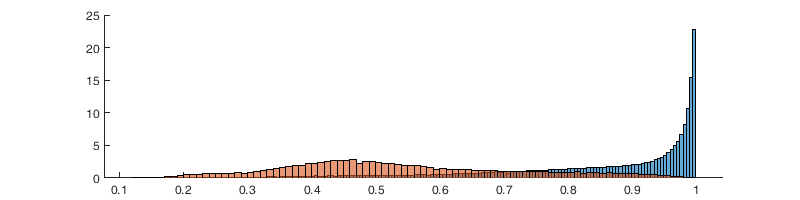

figure('position',[0 0 800 200]); hold on;
histogram(BS.predicted_class_prob(~BS.isBird),'Normalization','pdf')
histogram(BS.predicted_class_prob(BS.isBird),'Normalization','pdf')

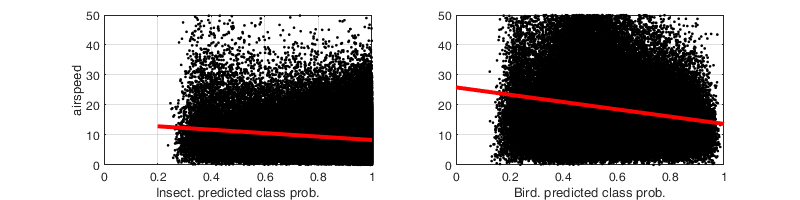

figure('position',[0 0 800 200]); hold on; 
subplot(1,2,1)
plot(BS.predicted_class_prob(~BS.isBird),abs(BS.air(~BS.isBird)),'.k');
h=lsline; h.LineWidth = 3; h.Color='r';
axis([0 1 0 50 ]); grid on; ylabel('airspeed'); xlabel('Insect. predicted class prob.')
subplot(1,2,2)
plot(BS.predicted_class_prob(BS.isBird),abs(BS.air(BS.isBird)),'.k');
h=lsline; h.LineWidth = 3; h.Color='r';
axis([0 1 0 50 ]); grid on;  xlabel('Bird. predicted class prob.')

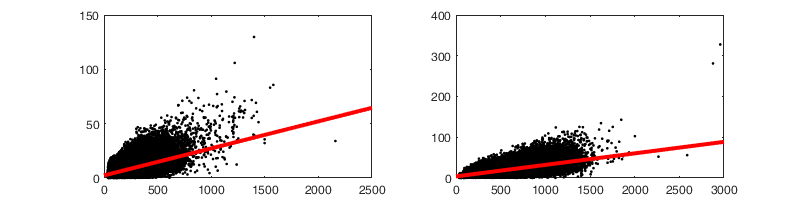

figure('position',[0 0 800 200]); hold on; 
subplot(1,2,1)
plot(BS.altitude(~BS.isBird),abs(BS.air(~BS.isBird)),'.k');
h=lsline; h.LineWidth = 3; h.Color='r';
subplot(1,2,2)
plot(BS.altitude(BS.isBird),abs(BS.air(BS.isBird)),'.k');
h=lsline; h.LineWidth = 3; h.Color='r';

Description of the data

fprintf(['Number of insect track: ' num2str(sum(~BS.isBird)) ' (nan: ' num2str(mean(isnan(BS.flight(~BS.isBird)))*100,2) 'perc.) \nNumber of bird track: ' num2str(sum(BS.isBird)) ' (nan: ' num2str(mean(isnan(BS.flight(BS.isBird)))*100,2) 'perc)'])

Number of insect track: 626006 (nan: 62perc.) 
Number of bird track: 234199 (nan: 59perc)

minprob=.3;
maxalt = 500;
minalt = 50;
BSs = BS(BS.predicted_class_prob>minprob & abs(BS.air)<30 & BS.altitude>minalt & BS.altitude<maxalt,:);
disp(['Filter kept ' num2str(round(size(BSs,1)/size(BS,1)*100)) '% of the data'])

Filter kept 32% of the data


fprintf(['Number of insect track: ' num2str(sum(~BSs.isBird)) ' \nNumber of bird track: ' num2str(sum(BSs.isBird)) ])

Number of insect track: 230214 
Number of bird track: 42573

Description of the speed

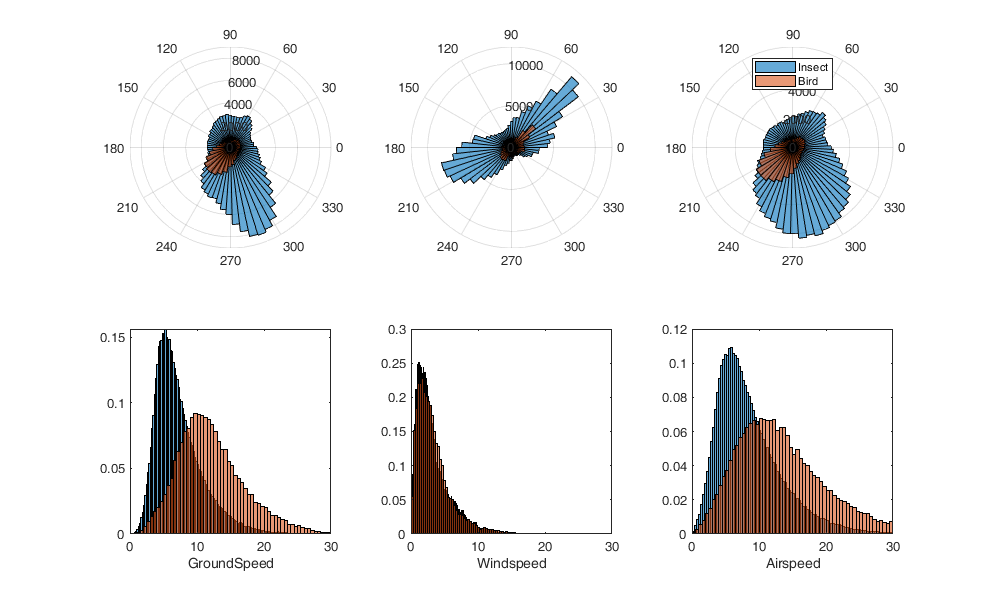

figure('position',[0 0 1000 600])
subplot(2,3,1)
polarhistogram(angle(BSs.flight(~BSs.isBird))); hold on;
polarhistogram(angle(BSs.flight(BSs.isBird)));
subplot(2,3,2)
polarhistogram(angle(BSs.wind(~BSs.isBird))); hold on;
polarhistogram(angle(BSs.wind(BSs.isBird)));
subplot(2,3,3)
polarhistogram(angle(BSs.air(~BSs.isBird))); hold on;
polarhistogram(angle(BSs.air(BSs.isBird)));
legend({'Insect','Bird'},'Location','north')
subplot(2,3,4)
histogram(abs(BSs.flight(~BSs.isBird)),'Normalization','pdf'); hold on;
histogram(abs(BSs.flight(BSs.isBird)),'Normalization','pdf');
xlabel('GroundSpeed'); xlim([0 30])
subplot(2,3,5)
histogram(abs(BSs.wind(~BSs.isBird)),'Normalization','pdf'); hold on;
histogram(abs(BSs.wind(BSs.isBird)),'Normalization','pdf');
xlabel('Windspeed'); xlim([0 30])
subplot(2,3,6)
histogram(abs(BSs.air(~BSs.isBird)),'Normalization','pdf'); hold on;
histogram(abs(BSs.air(BSs.isBird)),'Normalization','pdf');
xlabel('Airspeed'); xlim([0 30])

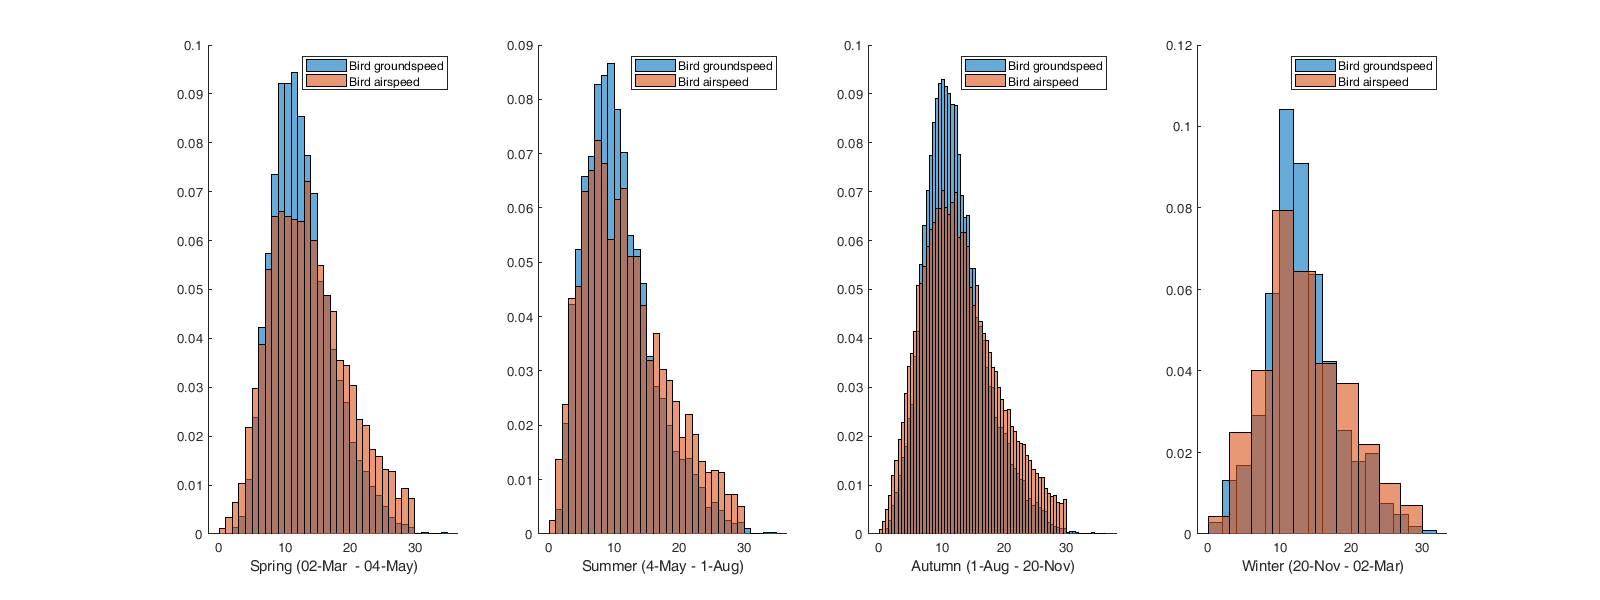

figure('position',[0 0 1600 600]); hold on;
for i_s=1:4
    subplot(1,4,i_s); hold on;
    histogram(abs(BSs.flight(BSs.isBird & BSs.season==i_s)),'Normalization','pdf')
    histogram(abs(BSs.air(BSs.isBird & BSs.season==i_s)),'Normalization','pdf')
    xlabel(season_label{i_s})
    legend({'Bird groundspeed','Bird airspeed'})
end

## Nighly average

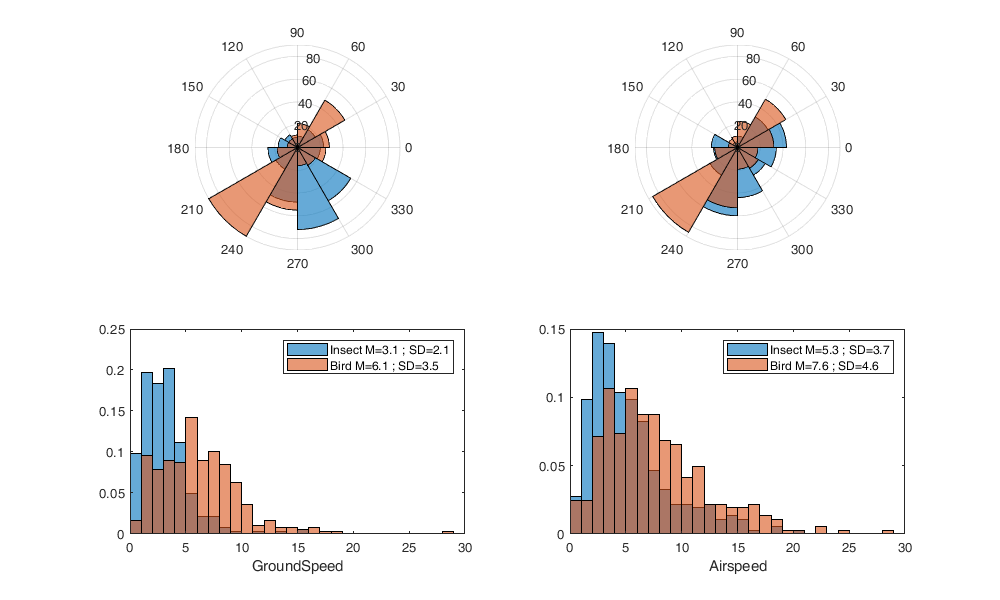

bird_flight = nan(1,numel(t)); bird_air = nan(1,numel(t));
insect_flight = nan(1,numel(t)); insect_air = nan(1,numel(t));

[G,ID] = findgroups(BSs.day_id(BSs.isBird));
bird_flight(ID) = splitapply(@mean, BSs.flight(BSs.isBird), G);
bird_air(ID) = splitapply(@mean, BSs.air(BSs.isBird), G);

[G,ID] = findgroups(BSs.day_id(~BSs.isBird));
insect_flight(ID) = splitapply(@mean, BSs.flight(~BSs.isBird), G);
insect_air(ID) = splitapply(@mean, BSs.air(~BSs.isBird), G);

figure('position',[0 0 1000 600])
subplot(2,2,1)
polarhistogram(angle(insect_flight),12); hold on;
polarhistogram(angle(bird_flight),12)
subplot(2,2,2)
polarhistogram(angle(insect_air),12); hold on;
polarhistogram(angle(bird_air),12);
subplot(2,2,3)
histogram(abs(insect_flight),0:1:30,'Normalization','pdf'); hold on;
histogram(abs(bird_flight),0:1:30,'Normalization','pdf');
legend({['Insect M=' num2str(round(nanmean(abs(insect_flight)),1)) ' ; SD=' num2str(round(nanstd(abs(insect_flight)),1)) ],['Bird M=' num2str(round(nanmean(abs(bird_flight)),1)) ' ; SD=' num2str(round(nanstd(abs(bird_flight)),1)) ]})
xlabel('GroundSpeed'); xlim([0 30])
subplot(2,2,4)
histogram(abs(insect_air),0:1:30,'Normalization','pdf'); hold on;
histogram(abs(bird_air),0:1:30,'Normalization','pdf');
legend({['Insect M=' num2str(round(nanmean(abs(insect_air)),1)) ' ; SD=' num2str(round(nanstd(abs(insect_air)),1)) ],['Bird M=' num2str(round(nanmean(abs(bird_air)),1)) ' ; SD=' num2str(round(nanstd(abs(bird_air)),1)) ]})
xlabel('Airspeed'); xlim([0 30])

Compute the mean absolute flight per day of all object combined

[~,Locb] = ismember(dateshift(BSs.time_string,'start','day'),t);
[C,~,ic] = unique(Locb);
absflight(C) = splitapply(@mean, abs(BSs.flight), ic);

## Averaging produced by WR

Roughly accounting for volume size difference with WR

Radius of weather radar (WR) and birdscan (BS). We compute the average beam width from the beam angle and the height used

rWR = 25;
baBS = 17.5;% beam angle deg
rBS = @(h) h*tand(baBS);

Volume covered by WR (no coverage within first 5km

VWR = rWR^2*pi-5^2*pi

VWR = 1.8850e+03

VBS = rBS(maxalt/1000)^2*pi*maxalt/1000/3 - rBS(minalt/1000)^2*pi*minalt/1000/3

VBS = 0.0130

The duration can be found from speed.

dtBS = @(v) (VWR - VBS) / (2*rBS((maxalt+minalt)/2/1000)*v);

Assume a initial bird speed of 10 m/s -> 864 km/day

dtBS(10/1000*60*60*24)

ans = 12.5805

dtBS(20/1000*60*60*24)

ans = 6.2903

This would require to do average over 10+ days. NOT POSSIBLE

Attempt to upscale the distribution

Y=nan(4,numel(t),3);
for i_t=1:numel(t)
    X=BSs.flight(BSs.day_id==i_t & ~BSs.isBird);
    if (size(X,1))>5
        Y(1,i_t,1)=mean(abs(X));
        Y(1,i_t,2)=quantile(abs(X),.1);
        Y(1,i_t,3)=quantile(abs(X),.9);
        Y(2,i_t,1)=abs(mean(X));
        Y(2,i_t,2)=abs(quantile(X,.1));
        Y(2,i_t,3)=abs(quantile(X,.9));
        
        nb_day = dtBS(mean(abs(X))/1000*60*60*24);
        
        X=[real(X) imag(X)];
        
        [f,xi] = ksdensity(X);
        
        xiid = datasample(1:numel(f),round(nb_day*size(X,1)),'weight',f);
        
        SimSam = xi(xiid,1) + xi(xiid,2)*1i;
        Y(3,i_t,1)=mean(abs(SimSam));
        Y(3,i_t,2)=quantile(abs(SimSam),0.1);
        Y(3,i_t,3)=quantile(abs(SimSam),0.9);
        Y(4,i_t,1)=abs(mean(SimSam));
        Y(4,i_t,2)=abs(quantile(SimSam,0.1));
        Y(4,i_t,3)=abs(quantile(SimSam,0.9));
    end
end

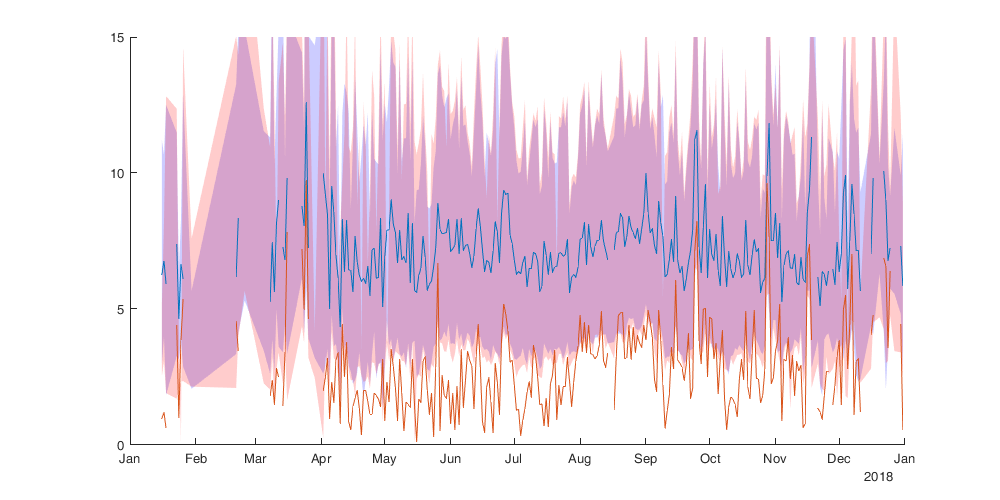

figure('position',[0 0 1000 500]); hold on;
%plot(t,Y)
%legend({'Mean of flight speed over day', 'Speed of flight mean over day', 'Mean of flight speed for volume', 'Speed of flight mean for volume'})

idt=~any(isnan(Y(:,:,1)));
fill([t(idt), fliplr(t(idt))], [Y(1,idt,2), fliplr(Y(1,idt,3))],'b','FaceAlpha',.2,'EdgeColor','none')
fill([t(idt), fliplr(t(idt))], [Y(4,idt,2), fliplr(Y(4,idt,3))],'r','FaceAlpha',.2,'EdgeColor','none')
plot(t,Y([1 4],:,1)); ylim([0 15])

% legend({'Mean of flight speed over day', 'Speed of flight mean over day', 'Mean of flight speed for volume', 'Speed of flight mean for volume'})